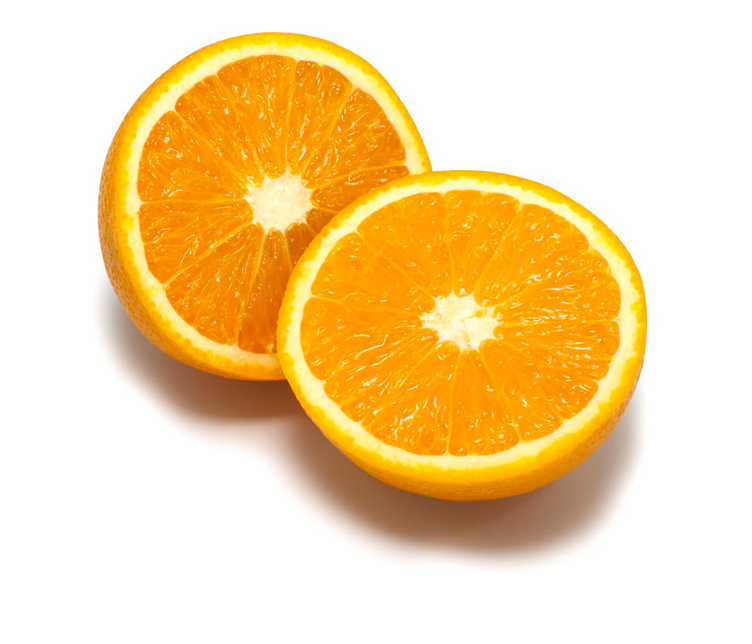

K = 8;               % number of clusters used
L = 6;              % number of iterations
seed = 20;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

I = imread('orange.jpg');
imshow(I);

I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

% [ segm, centers ] = kmeans_segm(I, K, L, seed);
% disp(centers);
% Inew = mean_segments(Iback, segm);
% I = overlay_bounds(Iback, segm);
% imshow(Inew);
% imshow(I);

for L = 1:20
    [ segm, centers ] = kmeans_segm(I, K, L, seed);
    disp(centers);
end

   253   177     6
   253   160     3
   254   254   253
   214   125    18
   228   211   166
   253   149     4
   233   184    73
   251   155     6



   253   186    11
   253   161     2
   254   253   252
   176   107    42
   234   218   166
   248   144     2
   227   181    85
   248   156    12



   253   192    15
   253   161     2
   254   253   253
   156   103    65
   237   222   167
   242   139     3
   227   183    95
   246   158    20



   253   197    16
   253   160     3
   254   253   253
   153   105    71
   239   224   169
   238   135     3
   228   187   103
   246   162    27



   254   200    15
   252   160     3
   254   253   253
   154   105    72
   239   225   171
   236   133     4
   228   190   109
   247   167    33



   254   202    13
   252   159     3
   254   253   253
   154   106    73
   240   226   172
   235   132     4
   227   191   114
   247   172    38



   254   202    11
   252   159     4
   254   253   253
   154   106    73
   240   226   173
   234   132     4
   225   192   119
   248   175    42



   254   201    10
   252   159     4
   254   253   253
   154   105    73
   245   231   173
   234   131     5
   217   190   131
   248   179    46



   254   200     8
   252   159     4
   254   253   253
   153   105    72
   248   233   171
   233   131     5
   208   183   141
   249   185    53



   254   199     7
   252   159     5
   254   253   253
   153   104    70
   249   234   167
   233   131     5
   195   172   153
   250   192    61



   254   198     8
   252   159     5
   254   253   253
   152   103    69
   250   234   166
   233   131     5
   191   169   154
   250   196    67



   254   197     9
   252   159     5
   254   253   253
   152   102    69
   249   234   167
   233   131     6
   191   169   153
   250   198    71



   254   196    10
   252   159     5
   254   253   253
   152   102    68
   249   234   168
   233   131     6
   190   168   153
   250   200    74



   253   195    11
   252   159     5
   254   253   253
   152   102    68
   249   234   169
   233   131     6
   190   167   152
   250   201    77



   253   194    12
   252   159     5
   254   253   253
   152   102    68
   249   234   170
   233   131     6
   190   167   152
   250   203    79



   253   193    13
   252   158     5
   254   253   253
   152   102    68
   249   234   170
   233   131     6
   190   167   152
   250   204    81



   253   192    14
   251   158     5
   254   253   253
   152   102    68
   249   234   171
   232   131     6
   190   167   152
   251   205    83



   253   192    15
   251   158     5
   254   253   253
   152   102    68
   248   234   171
   232   130     6
   190   167   151
   251   206    85



   253   192    16
   251   158     5
   254   253   253
   152   102    68
   248   234   172
   231   130     6
   189   167   151
   251   207    86



   253   191    16
   251   158     5
   254   253   253
   152   102    68
   248   234   172
   231   130     6
   189   166   151
   251   208    87

